N     = 64;     % Order
Fs    = 44100;  % Sampling Frequency

Fpass = 2000;   % Passband Frequency
Fstop = 2250;   % Stopband Frequency

h = fdesign.lowpass('n,fp,fst', N, Fpass, Fstop, Fs);

H1 = design(h, 'firls');
H1_coeffs = coeffs(H1);
H1_coeffs.Numerator

ans =    -0.0021    0.0005    0.0033    0.0061    0.0085    0.0103    0.0112    0.0112    0.0102    0.0080    0.0049    0.0009   -0.0036   -0.0083   -0.0127   -0.0165   -0.0191   -0.0203   -0.0197   -0.0170   -0.0121   -0.0052    0.0037    0.0143    0.0261    0.0387    0.0513    0.0634    0.0743    0.0835    0.0904    0.0947    0.0962    0.0947    0.0904    0.0835    0.0743    0.0634    0.0513    0.0387    0.0261    0.0143    0.0037   -0.0052   -0.0121   -0.0170   -0.0197   -0.0203   -0.0191   -0.0165


Fstop1 = 2000;   % First Stopband Frequency
Fpass1 = 2250;   % First Passband Frequency
Fpass2 = 4250;   % Second Passband Frequency
Fstop2 = 4500;   % Second Stopband Frequency

h = fdesign.bandpass('n,fst1,fp1,fp2,fst2', N, Fstop1, Fpass1, Fpass2, ...
    Fstop2, Fs);

H2 = design(h, 'firls');
H2_coeffs = coeffs(H2);
H2_coeffs.Numerator

ans =     0.0099    0.0038   -0.0046   -0.0129   -0.0187   -0.0202   -0.0170   -0.0101   -0.0019    0.0048    0.0079    0.0069    0.0027   -0.0018   -0.0036   -0.0003    0.0088    0.0214    0.0335    0.0400    0.0364    0.0208   -0.0051   -0.0361   -0.0642   -0.0814   -0.0814   -0.0622   -0.0266    0.0178    0.0607    0.0916    0.1029    0.0916    0.0607    0.0178   -0.0266   -0.0622   -0.0814   -0.0814   -0.0642   -0.0361   -0.0051    0.0208    0.0364    0.0400    0.0335    0.0214    0.0088   -0.0003


Fstop1 = 4250;   % First Stopband Frequency
Fpass1 = 4500;   % First Passband Frequency
Fpass2 = 6500;   % Second Passband Frequency
Fstop2 = 6750;   % Second Stopband Frequency

h = fdesign.bandpass('n,fst1,fp1,fp2,fst2', N, Fstop1, Fpass1, Fpass2, ...
    Fstop2, Fs);

H3 = design(h, 'firls');
H3_coeffs = coeffs(H3);
H3_coeffs.Numerator

ans =    -0.0159   -0.0119    0.0007    0.0145    0.0202    0.0137   -0.0007   -0.0133   -0.0164   -0.0095    0.0003    0.0050    0.0024   -0.0018    0.0002    0.0103    0.0207    0.0190   -0.0006   -0.0299   -0.0488   -0.0389    0.0008    0.0498    0.0758    0.0572   -0.0007   -0.0651   -0.0954   -0.0693    0.0003    0.0722    0.1025    0.0722    0.0003   -0.0693   -0.0954   -0.0651   -0.0007    0.0572    0.0758    0.0498    0.0008   -0.0389   -0.0488   -0.0299   -0.0006    0.0190    0.0207    0.0103


Fstop1 = 6500;   % First Stopband Frequency
Fpass1 = 6750;   % First Passband Frequency
Fpass2 = 8750;   % Second Passband Frequency
Fstop2 = 9000;   % Second Stopband Frequency

h = fdesign.bandpass('n,fst1,fp1,fp2,fst2', N, Fstop1, Fpass1, Fpass2, ...
    Fstop2, Fs);

H4 = design(h, 'firls');
H4_coeffs = coeffs(H4);
H4_coeffs.Numerator

ans =     0.0114    0.0165    0.0024   -0.0164   -0.0177    0.0008    0.0178    0.0142   -0.0034   -0.0134   -0.0071    0.0025    0.0024   -0.0014    0.0043    0.0141    0.0077   -0.0181   -0.0333   -0.0088    0.0379    0.0509    0.0027   -0.0607   -0.0629    0.0103    0.0820    0.0661   -0.0279   -0.0971   -0.0599    0.0460    0.1025    0.0460   -0.0599   -0.0971   -0.0279    0.0661    0.0820    0.0103   -0.0629   -0.0607    0.0027    0.0509    0.0379   -0.0088   -0.0333   -0.0181    0.0077    0.0141


Fstop1 = 8750;   % First Stopband Frequency
Fpass1 = 9000;   % First Passband Frequency
Fpass2 = 11000;  % Second Passband Frequency
Fstop2 = 11250;  % Second Stopband Frequency

h = fdesign.bandpass('n,fst1,fp1,fp2,fst2', N, Fstop1, Fpass1, Fpass2, ...
    Fstop2, Fs);

H5 = design(h, 'firls');
H5_coeffs = coeffs(H5);
H5_coeffs.Numerator

ans =     0.0006   -0.0172   -0.0061    0.0176    0.0118   -0.0145   -0.0155    0.0090    0.0154   -0.0030   -0.0108   -0.0005    0.0025   -0.0009    0.0070    0.0086   -0.0142   -0.0222    0.0157    0.0393   -0.0088   -0.0558   -0.0069    0.0673    0.0297   -0.0698   -0.0557    0.0611    0.0797   -0.0419   -0.0966    0.0149    0.1027    0.0149   -0.0966   -0.0419    0.0797    0.0611   -0.0557   -0.0698    0.0297    0.0673   -0.0069   -0.0558   -0.0088    0.0393    0.0157   -0.0222   -0.0142    0.0086


Fstop1 = 11000;  % First Stopband Frequency
Fpass1 = 11250;  % First Passband Frequency
Fpass2 = 13250;  % Second Passband Frequency
Fstop2 = 13500;  % Second Stopband Frequency

h = fdesign.bandpass('n,fst1,fp1,fp2,fst2', N, Fstop1, Fpass1, Fpass2, ...
    Fstop2, Fs);

H6 = design(h, 'firls');
H6_coeffs = coeffs(H6);
H6_coeffs.Numerator

ans =    -0.0123    0.0133    0.0096   -0.0185   -0.0037    0.0202   -0.0032   -0.0172    0.0081    0.0107   -0.0082   -0.0035    0.0023   -0.0005    0.0081   -0.0024   -0.0194    0.0136    0.0265   -0.0317   -0.0246    0.0525    0.0111   -0.0695    0.0130    0.0768   -0.0433   -0.0702    0.0730    0.0493   -0.0946   -0.0178    0.1026   -0.0178   -0.0946    0.0493    0.0730   -0.0702   -0.0433    0.0768    0.0130   -0.0695    0.0111    0.0525   -0.0246   -0.0317    0.0265    0.0136   -0.0194   -0.0024


Fstop1 = 13250;  % First Stopband Frequency
Fpass1 = 13500;  % First Passband Frequency
Fpass2 = 15500;  % Second Passband Frequency
Fstop2 = 15750;  % Second Stopband Frequency

h = fdesign.bandpass('n,fst1,fp1,fp2,fst2', N, Fstop1, Fpass1, Fpass2, ...
    Fstop2, Fs);

H7 = design(h, 'firls');
H7_coeffs = coeffs(H7);
H7_coeffs.Numerator

ans =     0.0157   -0.0063   -0.0123    0.0194   -0.0057   -0.0144    0.0187   -0.0036   -0.0126    0.0128   -0.0012   -0.0056    0.0021    0.0001    0.0071   -0.0121   -0.0013    0.0249   -0.0276   -0.0062    0.0459   -0.0416   -0.0147    0.0672   -0.0519   -0.0258    0.0856   -0.0566   -0.0379    0.0981   -0.0553   -0.0485    0.1025   -0.0485   -0.0553    0.0981   -0.0379   -0.0566    0.0856   -0.0258   -0.0519    0.0672   -0.0147   -0.0416    0.0459   -0.0062   -0.0276    0.0249   -0.0013   -0.0121


Fstop1 = 15500;  % First Stopband Frequency
Fpass1 = 15750;  % First Passband Frequency
Fpass2 = 17750;  % Second Passband Frequency
Fstop2 = 18000;  % Second Stopband Frequency

h = fdesign.bandpass('n,fst1,fp1,fp2,fst2', N, Fstop1, Fpass1, Fpass2, ...
    Fstop2, Fs);

H8 = design(h, 'firls');
H8_coeffs = coeffs(H8);
H8_coeffs.Numerator

ans =    -0.0090   -0.0026    0.0148   -0.0197    0.0135    0.0006   -0.0138    0.0184   -0.0124    0.0013    0.0067   -0.0070    0.0022    0.0005    0.0041   -0.0135    0.0181   -0.0089   -0.0140    0.0383   -0.0455    0.0245    0.0187   -0.0606    0.0737   -0.0444   -0.0157    0.0738   -0.0949    0.0632    0.0061   -0.0745    0.1027   -0.0745    0.0061    0.0632   -0.0949    0.0738   -0.0157   -0.0444    0.0737   -0.0606    0.0187    0.0245   -0.0455    0.0383   -0.0140   -0.0089    0.0181   -0.0135


Ht = parallel(cascade(1,H1),cascade(1,H2),cascade(1,H3),cascade(1,H4),cascade(1,H5),cascade(1,H6),cascade(1,H7),cascade(1,H8));
sine_sum_filtered = filter(Ht, sine_total);

% signal_fft = fftshift(fft(sine_sum_filtered))/length(sine_sum_filtered);
signal_fft = fftshift(fft(sine_sum_filtered));
% signal_fft = fft(sine_sum_filtered);
df = fs/length(sine_sum_filtered);
half_res = df/2;
freq = -fs/2: df : fs/2 - df;

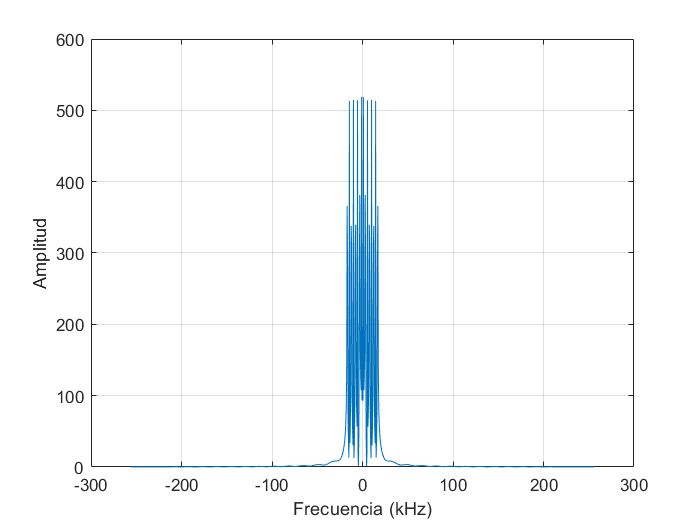

plot(freq/1e3, abs(signal_fft))
grid on
% xlim([-30 30])
xlabel("Frecuencia (kHz)")
ylabel("Amplitud")

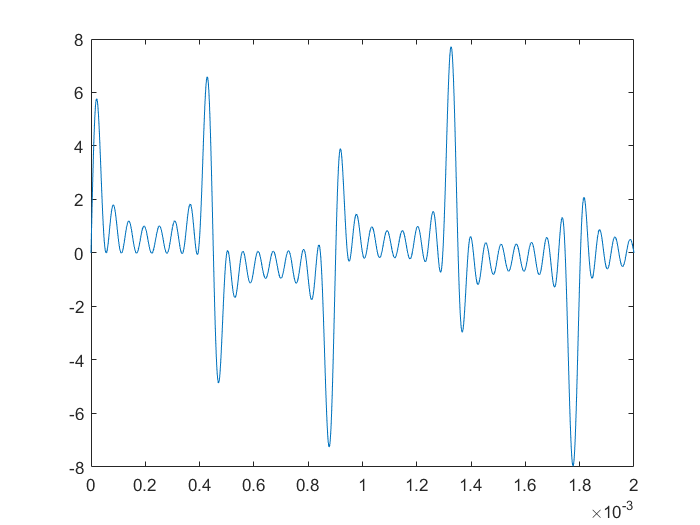

plot(t, sine_total)

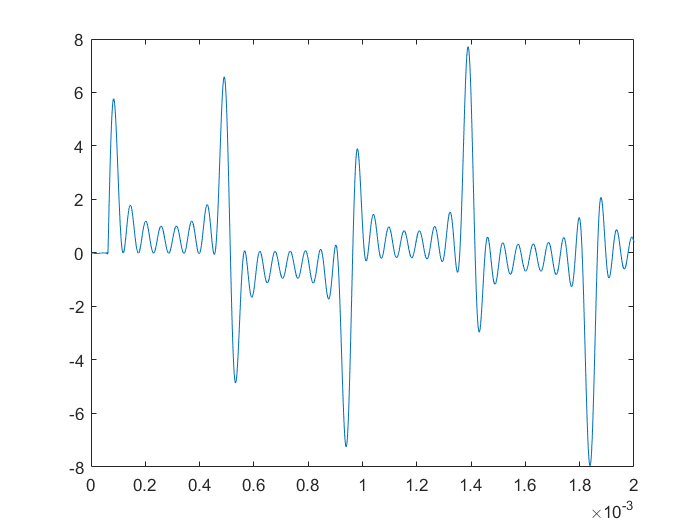

plot(t, sine_sum_filtered)

mean_values = zeros([1 8]);
abs_fft = abs(signal_fft);
for i = 1:8
    mean_values(i) = mean(abs_fft((32*(i-1)+1):(32*(i)+1)));
end
mean_values

mean_values =     0.1801    0.1831    0.2022    0.2744    0.3137    0.3431    0.3893    0.4499


fft_test_input = [
-0.865129623056441, 	-2.655020678073846, 	0.600664612949661, 	0.080378093886515, 	...
-2.899160484012034, 	2.563004262857762, 	3.078328403304206, 	0.105906778385130, 	...
0.048366940168201, 	-0.145696461188734, 	-0.023417155362879, 	2.127729174988954, 	...
-1.176633086028377, 	3.690223557991855, 	-0.622791766173194, 	0.722837373872203, 	...
2.739754205367484, 	-0.062610410524552, 	-0.891296810967338, 	-1.845872258871811, 	...
1.195039415434387, 	-2.177388969045026, 	1.078649103637905, 	2.570976050490193, 	...
-1.383551403404574, 	2.392141424058873, 	2.858002843205065, 	-3.682433899725536, 	...
-3.488146646451150, 	1.323468578888120, 	-0.099771155430726, 	1.561168082500454, 	...
1.025026795103179, 	0.928841900171200, 	2.930499509864950, 	2.013349089766430, 	...
2.381676148486737, 	-3.081062307950236, 	-0.389579115537544, 	0.181540149166620, 	...
-2.601953341353208, 	0.333435137783218, 	-2.812945856162965, 	2.649109640172910, 	...
-1.003963025744654, 	1.552460768755035, 	0.088641345335247, 	-2.519951327113426, 	...
-4.341348988610527, 	0.557772429359965, 	-1.671267412948494, 	0.733951350960387, 	...
0.409263788034864, 	3.566033071952806, 	1.882565173848352, 	-1.106017073793287, 	...
0.154456720778718, 	-2.513205795512153, 	0.310978660939421, 	0.579706500111723, 	...
0.000086383683251, 	-1.311866980897721, 	1.840007477574986, 	-3.253005768451345, 	...
1.462584328739432, 	1.610103610851738, 	0.761914676858907, 	0.974541361089834, 	...
0.686845845885983, 	1.849153122025191, 	0.787800410401453, 	-1.187438909666279, 	...
-0.754937911044720, 	0.084373858395232, 	-2.600269011710521, 	-0.962982842142644, 	...
-0.369328108540868, 	0.810791418361879, 	3.587016488699641, 	-0.520776145083723, 	...
0.640249919627884, 	1.103122489464969, 	2.231779881455556, 	-1.308035392685241, 	...
0.424070304330106, 	-0.200383932651189, 	-2.365526783356541, 	-0.989114757436628, 	...
2.770807688959777, 	-0.444172737462307, 	0.079760979374078, 	-0.005199118412183, 	...
-0.664712668309527, 	-0.624171857561896, 	0.537306979007338, 	-2.575955675497642, 	...
1.562363235756780, 	1.814069369848895, 	-1.293428583392509, 	-1.026188449495686, 	...
-2.981771815588717, 	-4.223468103075124, 	2.672674782004045, 	-0.856096801117735, 	...
0.048517345512563, 	-0.026860721136222, 	0.392932277758187, 	-1.331740855093099, 	...
-1.894292129477081, 	-1.425006468460681, 	-2.721772427617057, 	-1.616831100216806, 	...
3.551177651488947, 	-0.069685667896087, 	-3.134634907409102, 	-0.263627598944639, 	...
-1.650469945991350, 	-2.203580339374399, 	-0.872203246123242, 	1.230782812607287, 	...
0.257288860093291, 	1.989083106173137, 	-1.985638729453261, 	-1.416185105842892, 	...
-1.131097688325772, 	-2.245130805416057, 	-1.938873996219074, 	2.043608361562645, 	...
-0.583727989880841, 	-1.785266378212929, 	1.961457586224753, 	1.139400099963223, 	...
-1.979519343363991, 	2.003023322818429, 	0.229004069076829, 	3.452808862193135, 	...
2.882273808365857, 	-1.549450501844438, 	-3.283872089931876, 	-0.327025884099064, 	...
-0.054979977136430, 	-1.192280531479012, 	0.645539328365578, 	2.300832863404618, 	...
-1.092951789535240, 	-1.017368249363773, 	-0.142673056169787, 	0.831073544881250, 	...
-2.314612531587064, 	-2.221456299106321, 	0.460261143885226, 	0.050585301888595, 	...
0.364373329183988, 	-1.685956552069538, 	0.050664512351055, 	-0.193355783902718, 	...
-0.158660446046828, 	2.394156453841953, 	-1.562965718554525, 	-2.199750600869900, 	...
1.544984022381773, 	-1.988307216807315, 	-0.628240722541046, 	-1.436235771505429, 	...
1.677013691147313, 	1.600741781678228, 	-0.757380959134706, 	-4.784797439515566, 	...
0.265121462834569, 	3.862029485934378, 	2.386823577249430, 	-3.655779745436893, 	...
-0.763541621368016, 	-1.182140388432962, 	-1.349106114858063, 	-2.287533624396759, 	...
-0.028603745188423, 	-1.353580755934427, 	0.461602380352937, 	-0.059599055078928, 	...
-0.929946734342228, 	0.065773089295561, 	1.106565863102982, 	4.719295086373593, 	...
-2.108377703544395, 	-2.226393620240159, 	1.375668397437521, 	-0.960772428525443, 	...
-2.156313465390571, 	1.126060012375311, 	2.756485137030720, 	0.739639690862600, 	...
3.914769510295006, 	1.685232785586675, 	4.079058040970612, 	-1.174598301660513, 	...
-2.885776587275580, 	-0.241073635188767, 	3.080489872502403, 	-2.051244183999421, 	...
0.664330486845139, 	-1.697798999370016, 	1.452369423649782, 	-1.523532831019280, 	...
0.171981186587481, 	-4.685274721583927, 	-1.336175835319380, 	1.419070770428945, 	...
-0.035791601713475, 	2.291937971632081, 	-1.962559313450293, 	-4.831595589339301, 	...
-1.857055284000925, 	2.606271522635512, 	-0.576447978738030, 	0.082299166967720, 	...
1.888399453494614, 	-3.564705298046079, 	-0.939357831083889, 	-1.903578203697778, 	...
-2.642492215447250, 	-0.182990405251017, 	3.742026478011174, 	0.104295803798333, 	...
1.848678195370347, 	-1.887384346896369, 	0.365048973046045, 	-0.889638010354219, 	...
1.173877118428863, 	-1.178562827540109, 	0.610271645685184, 	1.831284815697871, 	...
0.449575390102283, 	1.597171905253443, 	3.918574971904773, 	0.868104027970404, 	...
0.582643134746494, 	2.321256382353331, 	-0.238118642223180, 	-2.890287868054370, 	...
0.970995414625622, 	0.666137930891283, 	-0.202435718709502, 	2.057930200518194, 	...
3.120583443719949, 	-0.863945271701041, 	0.906848893874630, 	-1.434124930222570, 	...
0.754659384848783, 	-5.224154442713778, 	2.330229744098967, 	1.113946320164698, 	...
0.523324920322840, 	1.750740911548348, 	-0.899333972913577, 	0.228705845203506, 	...
-1.934782624767648, 	-3.508386237231303, 	-2.107108523073510, 	0.380587645474815, 	...
-0.476200877183279, 	-2.172086712642198, 	1.795372535780299, 	-2.100318983391055, 	...
-0.022571122461405, 	0.674514020010955, 	-0.148872569390857, 	0.298175890592737, 	...
-1.134244492493590, 	-3.146848422289455, 	-1.357950199087602, 	0.667362732020878, 	...
-3.119397998316724, 	-1.189341126297637, 	-1.532744386856668, 	-1.672972484202534, 	...
-2.042283373871558, 	-1.479481547595924, 	-0.002668662875396, 	0.262737760129546, 	...
2.734456080621830, 	-0.671945925075102, 	-3.735078262179111, 	-0.161705013319883, 	...
0.748963512361001, 	1.128046374367600, 	0.649651335592966, 	1.880020215025867, 	...
-1.095632293842306, 	1.197764876160487, 	0.323646656252985, 	-1.655502751114502, 	...
3.666399062961496, 	-0.334060899735197, 	-2.119056978738397, 	3.721375117275012, 	...
0.044874186872307, 	-2.733053897593234, 	1.590700278891042, 	3.215711772781902, 	...
-1.792085012843801, 	-0.405797188885475, 	-0.628080020080892, 	-1.831815840843960, 	...
2.973656862522834, 	-0.212032655138417, 	0.372437389437234, 	-1.614030579023492, 	...
-0.704900996358698, 	1.123700273452105, 	-0.136371848130819, 	3.020284357635585, 	...
-0.550211350877649, 	5.101256236381711, 	3.367051512192333, 	-4.385131946669234, 	...
-3.967303337694391, 	-0.965894936640022, 	0.328366945264681, 	0.199041562924914, 	...
1.067681999025495, 	-1.939516091697170, 	-1.092980954328824, 	0.273786079368066, 	...
-0.040928322190265, 	-0.118368078577437, 	1.766589628899997, 	1.738321311635393, 	...
-2.895012794321649, 	1.213521771395142, 	0.922971726633985, 	1.091516563636489, 	...
3.226378465469620, 	1.149169778666974, 	-1.695986327709386, 	-0.974803077355813, 	...
-4.898035507513607, 	1.622719302889447, 	0.583891313586579, 	-1.677182424094957, 	...
-1.915633132814685, 	-1.980150370851616, 	0.604538269404190, 	0.939862406149365, 	...
-1.266939874246416, 	-1.494771249200063, 	0.278042784093988, 	0.326627416008916, 	...
-1.914530157643303, 	1.908947721862196, 	0.531819285694044, 	3.056856632319658, 	...
-0.389241827774643, 	-2.418606606780420, 	0.915299238878703, 	-0.098774174295283, 	...
-0.906199428444304, 	0.316716451217743, 	-4.367700643578311, 	1.491687997515293, 	...
-1.962381126288365, 	-0.700829196527045, 	3.028958963615630, 	-2.313461067462598, 	...
-1.431933239886712, 	-0.831153039725342, 	3.939495598250743, 	0.342974753984771, 	...
-2.768330763002974, 	-2.744010370019008, 	3.821352685212561, 	4.551065271455856, 	...
3.270136437041298, 	-3.188028411950982, 	-0.777075012417436, 	0.097110650265216, 	...
1.221216137608812, 	-1.325824244541822, 	-2.655296734084113, 	-1.074792144885704, 	...
2.770401584439407, 	5.240270645610543, 	0.108576672208892, 	-1.209394350650142, 	...
1.403344353838785, 	-0.299032904177277, 	4.074959450638227, 	1.718727473952107, 	...
-3.061349227080806, 	-1.158596888541269, 	3.381858904662625, 	0.957339964054052, ...	
0.179900074904899, 	-3.909641902506081, 	0.805717289408649, 	2.047413793928261, 	...
-1.273580225826614, 	-2.681359186869971, 	-0.721241345822093, 	-1.613090681569475, 	...
0.463138804815955, 	0.377223507800954, 	2.046550684968141, 	0.178508732797712, 	...
-0.477815330358845, 	3.763355908332053, 	1.300430303035163, 	-0.214625793857725, 	...
1.343267891864081, 	-0.340007682433245, 	2.062703194680005, 	0.042032160234235, 	...
0.643732569732250, 	-1.913502543857589, 	3.771340762937158, 	1.050024807363386, 	...
-4.440489488592649, 	0.444904302066643, 	2.898702265650048, 	1.953232980548558, 	...
2.761564952735079, 	1.963537633260397, 	-2.168858472916215, 	-4.116235357699841, 	...
4.183678271896528, 	0.600422284944681, 	-0.659352647255126, 	-0.993127338218109, 	...
-2.463571314945747, 	0.937720951545881, 	-3.098957308429730, 	-2.354719140045463, 	...
-0.417285119323949, 	2.187974075975947, 	1.101468905172585, 	-3.185800678152109, 	...
2.357534709345083, 	0.246645606729407, 	4.440905650784504, 	-2.236807716637866, 	...
-2.171481518317550, 	-2.029571795072690, 	0.135599790431348, 	-1.277965265520191, 	...
-1.927976233157507, 	-5.434492783745394, 	-2.026375829312657, 	1.009666016819321, 	...
0.238549782367247, 	-0.516403923971309, 	-0.933977817429352, 	0.155803015935614, 	...
-0.396194809997929, 	-0.915178100253214, 	0.666329367985015, 	-1.517991149945785, 	...
0.458266744144822, 	-1.242845974381418, 	0.057914823556477, 	0.994101307476875, 	...
-2.387209849199325, 	0.459297048883826, 	0.227711405683905, 	0.030255073506117, 	...
-1.323361608181337, 	-4.650244457426706, 	0.062908579526021, 	3.462831028244432, 	...
1.303608183314856, 	-1.430415193881612, 	-1.672886118942142, 	0.992890699210099, 	...
-0.160814531784247, 	-1.238132939350430, 	-0.589223271459376, 	2.326363810561534, 	...
-4.433789496230785, 	1.664686987538929, 	-2.366128834617921, 	1.212421570743837, 	...
-4.847914267690055, 	0.228485221404712, 	0.466139765470957, 	-1.344202776943546, 	...
-1.012053673330574, 	-2.844980626424742, 	-1.552703722026340, 	-1.448830983885038, 	...
0.127010756753980, 	-1.667188263752299, 	3.424818052085100, 	0.956291135453840, 	...
-3.725533331754662, 	-1.584534272368832, 	-1.654148210472472, 	0.701610500675698, 	...
0.164954538683927, 	-0.739260064712987, 	-2.167324026090101, 	-0.310240491909496, 	...
-2.281790349106906, 	1.719655331305361, 	-2.997005923606441, 	-1.999301431556852, 	...
-0.292229010068828, 	1.172317994855851, 	0.196734885241533, 	2.981365193477068, 	...
2.637726016926352, 	1.434045125217982, 	0.883627180451827, 	-1.434040761445747, 	...
-1.528891971086553, 	-3.306913135367542, 	-0.399059265470646, 	-0.265674394285178, 	...
3.502591252855384, 	0.830301156604454, 	-0.220021317046083, 	-0.090553770476646, 	...
0.771863477047951, 	1.351209629105760, 	3.773699756201963, 	0.472600118752329, 	...
2.332825668012222, 	1.853747950314528, 	0.759515251766178, 	1.327112776215496, 	...
2.518730296237868, 	0.764450208786353, 	-0.278275349491296, 	-0.041559465082020, 	...
1.387166083167787, 	2.612996769598122, 	-0.385404831721799, 	2.005630016170309, 	...
-0.950500047307998, 	-1.166884021392492, 	1.432973552928162, 	2.540370505384567, 	...
-1.140505295054501, 	-3.673358835201185, 	-0.450691288038056, 	1.601024294408014, 	...
0.773213556014045, 	2.973873693246168, 	-1.361548406382279, 	1.409136332424815, 	...
-0.963382518314713, 	-2.031268227368161, 	0.983309972085586, 	-3.461412488471631, 	...
-2.601124929406039, 	-0.533896239766343, 	-2.627129008866350, 	0.622111169161305, 	...
-1.160926365580422, 	-2.406196188132628, 	-1.076870362758737, 	-1.791866820937175, 	...
-0.749453071522325, 	-5.324156615990973, 	-1.038698022238289, 	-2.106629944730630, 	...
0.659295598564773, 	0.520940881580988, 	-0.055649203928700, 	0.292096765423137, 	...
-4.663743901790872, 	-0.125066503391666, 	-2.452620252445380, 	-0.712128227397468, 	...
-0.048938037970968, 	-1.821520226003361, 	0.810106421304257, 	-0.196636623956257, 	...
-0.701769836763804, 	2.460345045649201, 	3.506597671641116, 	-2.711322611972225, 	...
-0.658079876600542, 	-2.040082099646173, 	2.201668355395807, 	1.181507395879711, 	...
-1.640739552179682, 	-1.613393726467190, 	-1.156741241731352, 	2.527773464519963, 	...
-0.497040638009502, 	-0.975817112895589, 	-2.866830755546166, 	1.120214498507878, 	...
5.986771654661698, 	0.398219252656757, 	-3.545606013198135, 	0.312398099396191, 	...
-2.265327979531788, 	0.792121001107366, 	-3.736145137670100, 	0.762228883650802, ...	
2.283545661214646, 	3.780020629583529, 	3.117260228608810, 	-2.011159255609613, 	...
0.279107700476072, 	2.003369134246936, 	-1.448171234480257, 	0.584697150310140, 	...
0.919508663636197, 	-3.071349141675388, 	-1.555923649263667, 	2.232497079438850, 	...
-0.012662139119883, 	0.372825540734715, 	2.378543590847629, 	1.459053407813062, 	...
-0.967913907390927, 	1.322825200678212, 	-1.033775820061824, 	-1.813629552693142, 	...
4.794348161661486, 	0.655279811518676, 	-2.224590138589720, 	0.595329481295766, 	...
3.364055988866225, 	1.863416422998127, 	1.930305751828105, 	-0.284467053432545, 	...
-0.923374905878938, 	1.922988234041399, 	0.310482143432719, 	0.332122302397134, 	...
-1.659487472408966, 	-1.865943507877961, 	-0.186775297569864, 	-1.700543850628361, 	...
0.497157959366735, 	-0.471244843957418, 	-0.432013753969948, 	-4.000189880113231, 	...
-0.415335170016467, 	0.317311950972859, 	0.038393428927595, 	0.177219909465206, 	...
0.531650958095143, 	-2.711644985175806, 	0.328744077805156, 	-0.938417707547928, 	...
0.970379584897379, 	1.873649473917137, 	0.177938226987023, 	0.155609346302393, 	...
-1.276504241867208, 	-0.463725075928807, 	-0.064748250389500, 	-1.725568534062385, 	...
-0.139066584804067, 	1.975514554117767, 	-0.807063199499478, 	-0.326926659682788, 	...
1.445727032487938, 	-0.597151107739100, 	2.732557531709386, 	-2.907130934109188, 	...
-1.461264832679981, 	-1.708588604968163, 	3.652851925431363, 	0.682050868282879, 	...
-0.281312579963294, 	0.554966483307825, 	-0.981341739340932, 	1.279543331141603, 	...
0.036589747826856, 	2.312073745896073, 	1.754682200732425, 	-0.957515875428627, 	...
-0.833596942819695, 	0.437054368791033, 	-0.898819399360279, 	-0.296050580896839, 	...
-0.785144257649601, 	-2.541503089003311, 	2.225075846758761, 	-1.587290487902002, 	...
-1.421404172056462, 	-3.015149802293631, 	1.780874288867949, 	-0.865812740882613, 	...
-2.845327531197112, 	1.445225867774367, 	2.183733236584647, 	1.163371072749080, 	...
0.883547693520409, 	-1.224093106684675, 	-1.854501116331044, 	1.783082089255796, 	...
2.301508706196191, 	-0.539901944139077, 	1.962315832319967, 	-0.060709041870503, 	...
-1.353139923300238, 	-1.482887537805234, 	1.273732601967176, 	-3.456609915556321, 	...
-3.752320586540873, 	3.536356614978951, 	0.206035952043233, 	5.933966913773842, 	...
-0.486633898075490, 	-0.329595089863342, 	1.496414153905337, 	0.137868749388880, 	...
-0.437192030996792, 	2.682750615210656, 	-2.440234892848570, 	1.433910252426186, 	...
-0.415051506104074, 	1.982003013708649, 	1.345796609972435, 	-2.335949513404370, 	...
1.065988867433025, 	2.741844905000464, 	-1.754047930934362, 	0.229252730015575, 	...
-0.679791016408669, 	-2.274097820043743, 	0.149802252231876, 	-0.139697151364830, 	...
-2.773367420505435, 	-4.403400246165611, 	-1.468974515184135, 	0.664990623095844, 	...
-3.446979775557143, 	1.850006428987618, 	-1.550866747921936, 	-3.632874882935257, 	...
0.828039662992464, 	2.794055182632816, 	-0.593995716682633, 	0.142788156054200, 	...
0.552461945119668, 	0.842127129738758, 	1.414335509600077, 	-0.311559241382430, 	...
1.510590844695250, 	1.692217183824300, 	0.613760285711957, 	0.065233463207770, 	...
-2.571912893711505, 	-1.707001531141341, 	0.673884968382041, 	0.889863883420103, 	...
-2.395635435233346, 	1.129247296359819, 	0.569074704779735, 	6.139436017480722, 	...
0.822158309259017, 	-3.289872016222589, 	0.417612988384414, 	1.493982103868165, 	...
-0.415353391377005, 	0.288670764933155, 	-1.895650228872272, 	-0.139631694475020, 	...
1.445103299005436, 	2.877182243683429, 	1.192428490172580, 	-5.964591921763842, 	...
0.570859795882959, 	2.328333316356666, 	0.333755014930026, 	1.221901577771909, 	...
0.943358697415568, 	2.793063983613067, 	3.163005066073616, 	2.098300664513867, 	...
-3.915313164333447, 	-2.475766769064539, 	1.720472044894277, 	-1.273591949275665, 	...
-1.213451272938616, 	0.697439404325690, 	-0.309902287574293, 	2.622575852162781, 	...
-2.075881936219060, 	0.777847545691770, 	-3.967947986440650, 	-3.066503371806472, 	...
1.193780625937845, 	0.214246579281311, 	-2.610681491162162, 	-1.261224183972745, 	...
-1.165071748544285, 	-1.116548474834374, 	0.847202164846982, 	-3.474301529532390, 	...
0.020799541946476, 	-3.868995473288166, 	1.757979409638067, 	0.868115130183109, 	...
0.910167436737958, 	-1.878855115563720, 	1.710357104174161, 	-1.468933980990902, 	...
1.799544171601169, 	-4.922332880027887, 	0.219424548939720, 	-0.971671113451924, 	...
-0.940533475616266, 	0.122510114412152, 	-1.373686254916911, 	1.760348103896323, 	...
0.391745067829643, 	2.521958505327354, 	-1.300693516405092, 	-0.538251788309178, 	...
0.797184135810173, 	2.908800548982588, 	1.590902251655215, 	-1.070323714487264, 	...
-3.349764443340999, 	-1.190563529731447, 	1.363369471291963, 	-1.814270299924576, 	...
-0.023381588315711, 	1.719182048679569, 	0.839917213252626, 	1.006099633839122, 	...
0.812462674381527, 	1.755814336346739, 	2.546848681206319, 	-1.555300208869455, 	...
1.017053811631167, 	0.996591039170903, 	-1.228047247924881, 	4.809462271463009, 	...
2.318113116151685, 	-1.206932520679733, 	1.273757685623312, 	0.724335352481802, 	...
1.519876652073198, 	-2.749670314714158, 	3.424042481847581, 	-3.714668360421517, 	...
1.612834197004014, 	-2.038234723985566, 	1.470938786562152, 	2.111634918450302, 	...
1.030376670151787, 	-0.420877189003829, 	-1.502024800532894, 	0.452310749163804, ...	
-1.606059382300987, 	-4.006159967834147, 	-2.152801208196508, 	1.671674089372579, 	...
1.714536333564101, 	-1.011518543005344, 	-0.576410282180584, 	0.733689809480836, 	...
1.004245602717974, 	1.010090391888449, 	3.811459513385621, 	-5.230621089271954, 	...
0.678044861034399, 	1.255935859598107, 	1.674521701615288, 	-1.656695216761705, 	...
1.169286028869693, 	0.524915416191998, 	2.397642885039520, 	2.108711400616072, 	...
2.037618211018084, 	-0.623664553406925, 	2.984106170984409, 	1.132182737400932, 	...
-2.859274340352130, 	-0.975550071398723, 	-1.359935119997407, 	-2.963308211050121, 	...
-0.228726662781163, 	-1.411110379682043, 	0.741553355734225, 	0.497554254758309, 	...
2.371907950598855, 	1.063465168988748, 	-0.641082692081488, 	-0.855439878540726, 	...
0.578321738578726, 	3.005809768796194, 	1.961458699064065, 	-3.206261663772745, 	...
-0.364431989095434, 	-0.263182496622273, 	1.843464680631139, 	-0.419107530229249, 	...
1.662335873298487, 	-0.853687563304005, 	-2.584133404357169, 	3.466839568922895, 	...
0.881671345091973, 	0.454620014206908, 	-1.737245187402739, 	2.162713238369243, 	...
-3.868539002714486, 	2.014114855933826, 	-0.703233831811006, 	-3.410319935997574, 	...
-1.851235811006584, 	0.909783907894036, 	0.091884002136728, 	-2.688294201131650, 	...
-0.906134178460955, 	3.475054609035133, 	-0.573927964170323, 	-0.429542937515399, 	...
0.991348618739939, 	1.974804904926325, 	0.975783450796698, 	-3.057119549071503, 	...
-3.899429237481194, 	0.362439009175350, 	-1.124461670265618, 	1.806000360163583, 	...
-2.768333362600288, 	0.244387897900379, 	0.908767296720926, 	1.254669374391882, 	...
-1.420441929463686, 	-0.875658895966293, 	0.183824603376167, 	-3.361653917011686, 	...
-0.796615630227952, 	-1.660226542658673, 	1.654439358307226, 	2.782812946709771, 	...
1.418064412811531, 	-0.819645647243761, 	0.807724772592699, 	-0.941967976379298, 	...
-2.312768306047469, 	0.872426936477443, 	0.919528961530845, 	-2.084904575264847, 	...
-1.972464868459322, 	-1.050687203338466, 	1.659579707007902, 	-1.820640014705855, 	...
-1.195078061671045, 	-1.639773173762048, 	1.616744338157063, 	4.019216096811563, 	...
3.461021102549681, 	1.642352734361484, 	-0.046354693720813, 	-0.041936252359677, 	...
-2.393307519480551, 	-0.341471634615121, 	-0.392073595257017, 	-0.219299018372730, 	...
-2.016391579662071, 	-0.653096251969787, 	1.466353155666821, 	-2.872058864320412, 	...
-2.157180779503830, 	0.723257479841560, 	3.769951308104384, 	-1.923392042420024, 	...
0.644899359942840, 	-2.090226891621437, 	-0.277043982890403, 	-0.528271428321112, 	...
2.518120645960652, 	1.040820431111488, 	-4.560583754742486, 	-0.226899614918836, 	...
1.713331231108959, 	-3.293941019163642, 	-1.113331444648290, 	-1.032308423149906, 	...
1.593774272982443, 	-1.246840475090529, 	-0.190344684920137, 	-1.719386356896355, 	...
-2.827721754659679, 	-0.092438285279020, 	-0.565844430675246, 	-1.077916121691716, 	...
-1.208665809504693, 	-2.996014266381254, 	2.888573323402423, 	2.829507048720695, 	...
-0.859177034120755, 	-1.969302377743254, 	0.777437674525362, 	-0.124910190157646, 	...
0.129875493115290, 	-4.192139262163992, 	3.023496047962126, 	1.149775163736637, 	...
2.038151304801731, 	3.016122489841263, 	-4.829481812137012, 	-1.668436615909279, 	...
0.958586784636918, 	1.550652410058678, 	-1.456305257976716, 	-0.079588392344731, 	...
-2.453213599392345, 	0.296795909127105, 	-0.253426616607643, 	1.418937160028195, 	...
-1.672949529066915, 	-1.620990298572947, 	-1.085103073196045, 	0.738606361195386, 	...
-2.097831202853255, 	2.711952282071310, 	1.498539238246888, 	1.317457282535915, 	...
-0.302765938349717, 	-0.044623707947201, 	2.337405215062395, 	-3.980689173859100, 	...
];

% fft_test_output = fftshift(fft(fft_test_input))/length(fft_test_input);
fft_test_output = fftshift(fft(fft_test_input));
% fft_test_output = fft(fft_test_input);
df = fs/length(fft_test_input);
half_res = df/2;
freq = -fs/2: df : fs/2 - df;

fft_test_abs = abs(fft_test_output)

fft_test_abs =    86.5394   38.1463   44.0099   52.6549   52.4160  113.7934   11.4104  122.7831   31.1504   90.0295   35.8419   19.5954   52.3435   41.1803   68.4856   61.2849   24.1649   82.9144   30.5207   24.3564   43.3724   57.0331   50.9751   12.2768   25.0482   48.6215   56.5225   23.0760   43.7423   84.5790   10.7796   53.9138   76.2832   52.9609   32.8414   49.7280   80.0972  108.2525   28.6508   14.9037   51.7874   89.6624   34.6658  138.8743   17.7860    5.7214  100.8169   50.7720   25.4041   76.3749


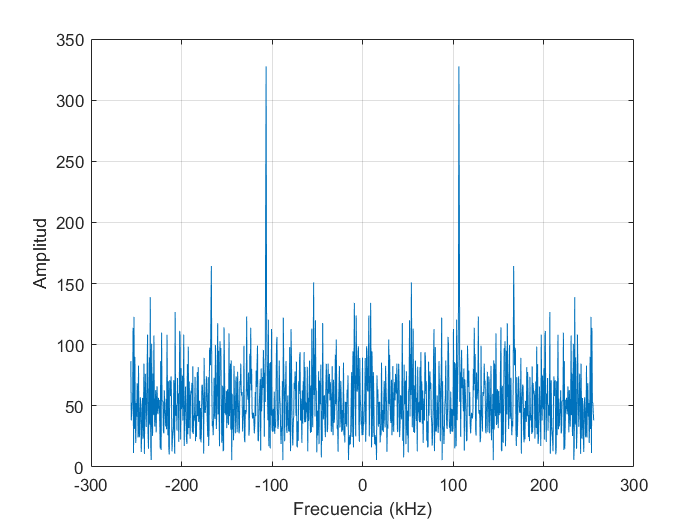

plot(freq/1e3, fft_test_abs)
grid on
% xlim([-30 30])
xlabel("Frecuencia (kHz)")
ylabel("Amplitud")

sosmatrix = [   0.5 -0.965247 0.469577 1 0.920261 -0.429433; ...
                0.5 -0.984162 0.485172 1 0.983325 -0.483781; ...
                0.081832 0.163664 0.081832 1 0.316046 -0.183314; ...
];
scalevalues = [1 1 1 1];
ivu = dsp.BiquadFilter(sosmatrix, scalevalues)

ivu =   dsp.BiquadFilter with properties:

                   Structure: 'Direct form II transposed'
             SOSMatrixSource: 'Property'
                   SOSMatrix: [3×6 double]
                 ScaleValues: [1 1 1 1]
           InitialConditions: 0
    OptimizeUnityScaleValues: true

  Show all properties


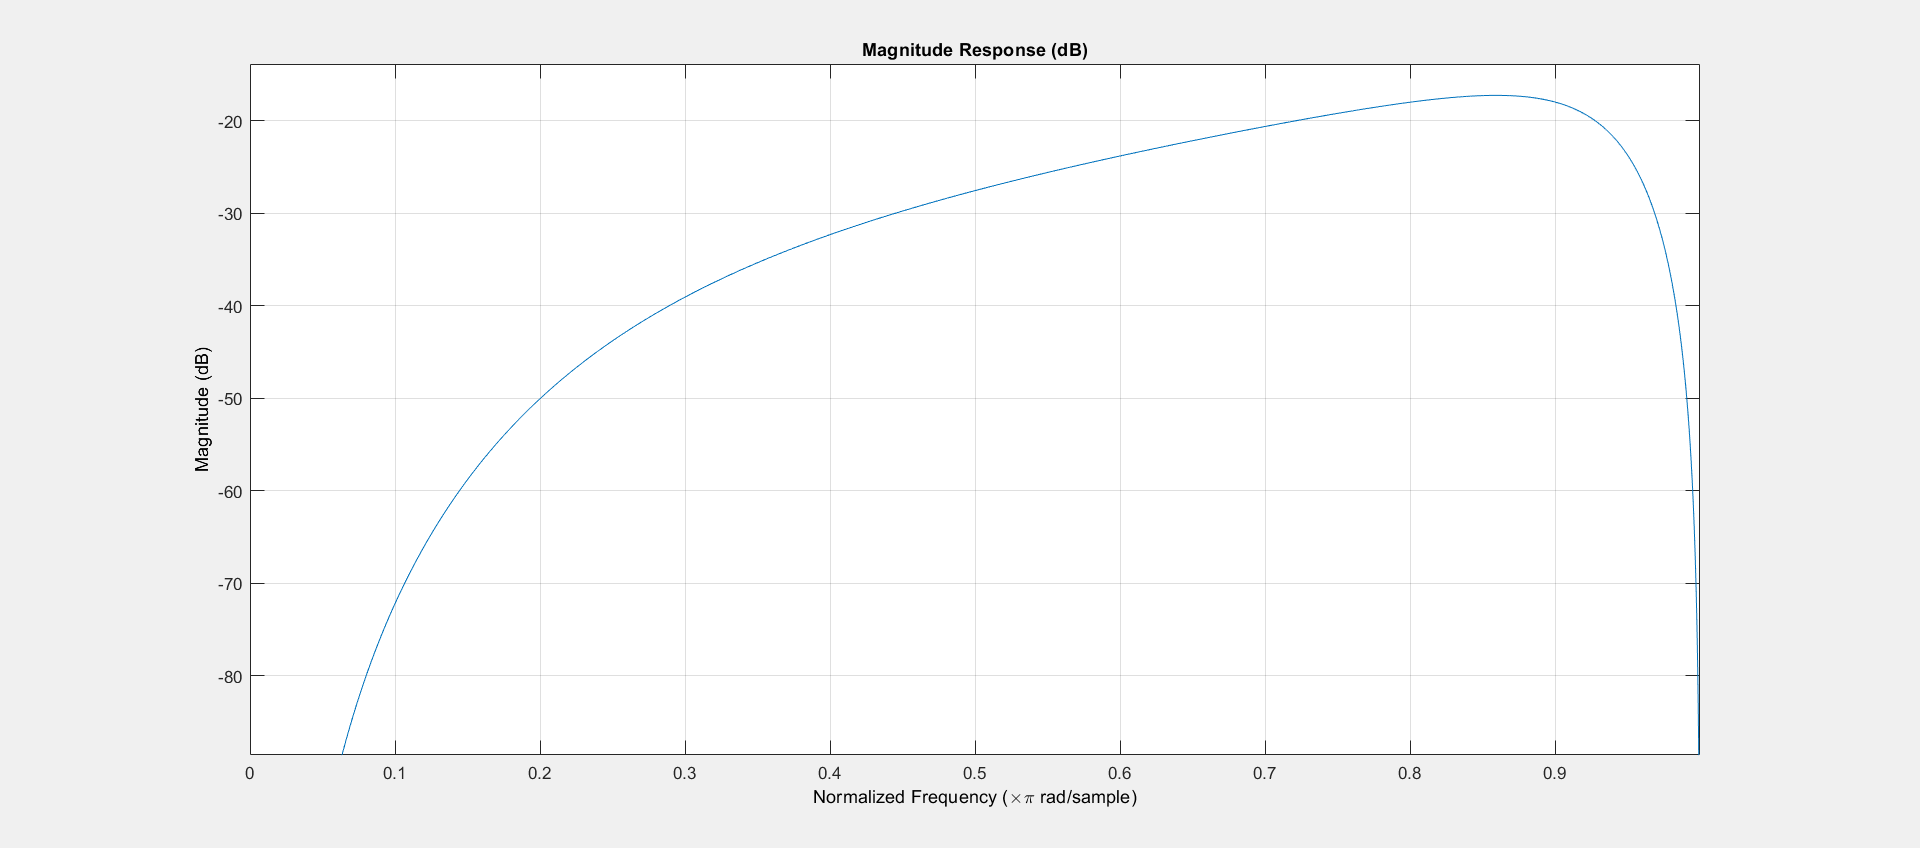

fvtool(ivu)